Consider the following constrained optimization problem:


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & -x_1^2 +4x_1 +x_2 \\
s\ldotp t & x_1^2 +x_2^2 -4x_1 \le 0\\
 & -x_2 \le 0
\end{array}\right.$$


close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

**a) Do global optimal solutions exist? Why?**

**b) Is it a convex problem? Why?**

It is a quadratic function with quadratic inequality constraint and a linear inequality constraint, we need to analyze if the convexity properties holds:

- Objective Function: $f\left(x\right)\;=\;-x_1^2 +4x_1 +x_2$

The objective function is a quadratic convex minimization with the form: $f\left(x\right)=\frac{1}{2}x^T Q\;x+q^T x+b$.  To prove the convexity, the Hessian Matrix Q has to be positive semi-definite. A matrix Q is positive-semidefinite if the eigenvalues of Q are non-negative.

- Inequality constraints:

-     
$${g_1 \left(x\right)=x}_1^2 +x_2^2 -4x_1 \le 0$$


-     
$$g_2 \left(x\right)=-x_2 \le 0$$


The constraint $g_1 \left(x\right)$ is quadratic convex constraint with the form: $g_1 \left(x\right)=\frac{1}{2}x^T A\;x+a^T x+b$. We can also see that this constraint is a circle. The evaluation of the Hessian matrix A has to be positive semi-definite. On the second hand, the constraint $g_2 \left(x\right)$ is linear constraint, and it is affine.

% Objective Function
Q = [-2 0
     0 0];

% Inequality constraint 
A = [2 0
     0 2];

fprintf("Eigen Value Objective Function:");

Eigen Value Objective Function:

display(eig(Q));

    -2
     0




fprintf("Eigen Value Constraint:");

Eigen Value Constraint:

display(eig(A));

     2
     2




fprintf("Determinant Value Objective Function:");

Determinant Value Objective Function:

display(det(Q));

     0




fprintf("Determinant Value Constraint:");

Determinant Value Constraint:

display(det(A));

     4



The objective function is negative-semidefinite, positive-semidefinite and concave. However, the problem is represented has a concave objective function and convex contraints, which still qualifies it as a convex problem. Therefore, the given problem is a convex optimization problem.

objective_function = @(x1, x2) -x1.^2 + 4.*x1 + x2;
constraint_1 = @(x1,x2) x1.^2 + x2.^2 - 4.*x1;
constraint_2 = @(x1,x2) -x2;

x1 = linspace(-5,5,150);
x2 = linspace(-5,5,150);

[X1,X2] = meshgrid(x1,x2);

X3 = objective_function(X1,X2);
C1 = constraint_1(X1,X2);
C2 = constraint_2(X1,X2);


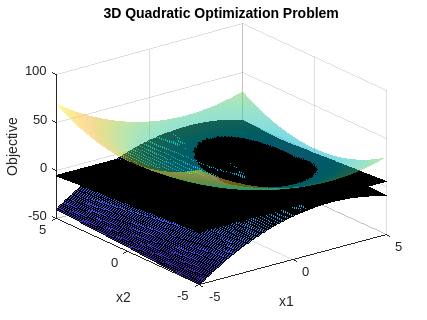

% 3D Plot
figure;
surf(X1,X2,X3);
hold on

surf(X1,X2,C1, 'FaceAlpha',0.5, 'EdgeColor','none');
surf(X1,X2,C2, 'FaceColor','none', 'FaceAlpha', 0.5);

xlabel('x1');
ylabel('x2');
zlabel('Objective');
title('3D Quadratic Optimization Problem')
view(3);
hold off

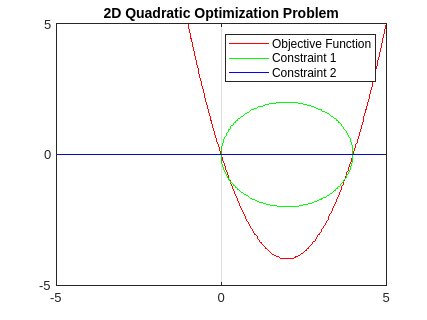

% 2D Plot
figure;
contour(X1,X2,X3, [0 0], 'r', 'LineWidth', 0.3);
hold on

contour(X1,X2,C1, [0 0], 'g',  'LineWidth', 0.3);
contour(X1,X2,C2, [0 0], 'b', 'LineWidth', 0.3);

legend('Objective Function', 'Constraint 1', 'Constraint 2');
xlim([-5 5]);
ylim([-5 5]);
title('2D Quadratic Optimization Problem');
grid on
hold off

**c) Does the Abadie constraints qualification hold in any feasible point? Why?**

**d) Find all the solutions of the KKT system.**


$$\left\lbrace \begin{array}{ll}
-2x_1 +4+{2\lambda }_1 x_1 -{4\lambda }_1  & =0\\
1+2\lambda_2 x_2 -\lambda_2  & =0\\
x_1^2 +x_2^2 -4x_1  & \le 0\\
-x_2  & \le 0\\
\lambda_1 \left(x_1^2 +x_2^2 -4x_1 \right) & =0\\
\lambda_2 \left(-x_2 \right) & =0\\
\lambda_1  & \ge 0\\
\lambda_2  & \ge 0
\end{array}\right.$$



$$-2x_1 +4+{2\lambda }_1 x_1 -{4\lambda }_1$$



$$1+2\lambda_2 x_2 -\lambda_2$$


syms x1 x2 lambda1 lambda2

equations = [-2*x1 + 4 + 2*lambda1*x1 - 4*lambda1 == 0
              1 + 2*lambda2*x2 - lambda2 == 0
              x1^2 + x2^2 - 4*x1 <= 0
             -x2 <= 0
              lambda1*(x1^2 + x2^2 - 4*x1) == 0
              lambda2*(-x2)
              lambda1 >= 0
              lambda2 >= 0]

$$equations = \left(\begin{array}{c} 2\,\lambda_{1}\,x_{1}-2\,x_{1}-4\,\lambda_{1}+4=0\\ 2\,\lambda_{2}\,x_{2}-\lambda_{2}+1=0\\ {x_{1}}^{2}-4\,x_{1}+{x_{2}}^{2}\leq 0\\ -x_{2}\leq 0\\ \lambda_{1}\,\left({x_{1}}^{2}-4\,x_{1}+{x_{2}}^{2}\right)=0\\ -\lambda_{2}\,x_{2}\\ 0\leq \lambda_{1}\\ 0\leq \lambda_{2} \end{array}\right)$$

% Compute analytic solution of a symbolic equation
solution = solve(equations,[sym('x1'),sym('x2'),sym('lambda1'),sym('lambda2')]);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
         x1: [3×1 sym]
         x2: [3×1 sym]
    lambda1: [3×1 sym]
    lambda2: [3×1 sym]


where


$$\left(\begin{array}{cccc} x_{1}\left(1\right) & x_{2}\left(1\right) & \lambda_{1}\left(1\right) & \lambda_{2}\left(1\right) \end{array}\right)=\left(\begin{array}{cccc} 2 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1}\left(2\right) & x_{2}\left(2\right) & \lambda_{1}\left(2\right) & \lambda_{2}\left(2\right) \end{array}\right)=\left(\begin{array}{cccc} 0 & 0 & 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1}\left(3\right) & x_{2}\left(3\right) & \lambda_{1}\left(3\right) & \lambda_{2}\left(3\right) \end{array}\right)=\left(\begin{array}{cccc} 4 & 0 & 1 & 1 \end{array}\right)$$


variables = [x1, x2, lambda1, lambda2];

[x1,x2,lambda1,lambda2] = solve(equations, variables)

$$x1 = \left(\begin{array}{c} 2\\ 0\\ 4 \end{array}\right)$$

$$x2 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$lambda1 = \left(\begin{array}{c} 0\\ 1\\ 1 \end{array}\right)$$

$$lambda2 = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

**e) Find local minima and global minima.**

**f) Find the objective function and constraints of the Lagrangian dual problem.**

syms x1 x2 lambda1 lambda2

% Define the Objective Function and the Constraints
objectiveFunction = -x1.^2 + 4.*x1 + x2;
constraint1 = x1.^2 + x2.^2 - 4.*x1;
constraint2 = -x2;

lagrangian = objectiveFunction + lambda1*(constraint1) + lambda2*(constraint2);

fprintf("Lagrangian Dual Optimization Problem");

Lagrangian Dual Optimization Problem

d_x1 = diff(lagrangian, x1);
d_x2 = diff(lagrangian, x2);
d_lambda1 = diff(lagrangian, lambda1);
d_lambda2 = diff(lagrangian, lambda2);

fprintf("Lagrangian Dual Optimization Problem");

Lagrangian Dual Optimization Problem

% Solve the Lagrangian Dual
equations = [d_x1 == 0
    d_x2 == 0
    d_lambda1 <= 0
    d_lambda2 <= 0
    lambda1>=0
    lambda2>=0]

$$equations = \left(\begin{array}{c} \lambda_{1}\,\left(2\,x_{1}-4\right)-2\,x_{1}+4=0\\ 2\,\lambda_{1}\,x_{2}-\lambda_{2}+1=0\\ {x_{1}}^{2}-4\,x_{1}+{x_{2}}^{2}\leq 0\\ -x_{2}\leq 0\\ 0\leq \lambda_{1}\\ 0\leq \lambda_{2} \end{array}\right)$$


sol = solve(equations)

